%% Constants
mu   = 398600.4418;          % [km^3/s^2]
Re   = 6378.1363;            % [km]
J2   = 1.08262668e-3;        % [-]
we   = 7.2921159e-5;         % [rad/s] Earth rotation (sidereal)

%% Assignment assumptions
Omega = deg2rad(0);
omega = deg2rad(0);
nu0   = deg2rad(0);       % true anomaly at t0

Defining Constants and Values for the functions

% Example initial elements (radians). Assignment says ω=Ω=ν=0°
a = 7000;                         % km  (pick any bound, elliptical orbit)
e = 0.01;
i = deg2rad(51.6);                % can be anything for 1a

t0 = 0;                           % s
n  = sqrt(mu/a^3);
T  = 2*pi/n;                      % one period
tf = 2*T;                         % propagate 2 orbits just to test
dt = 60;                          % reasonable step for 1a


Choose dt according to weakest chain in the OD

1b) SSO inclination (hp=550 km, e=0.01), propagate 30 revs

Re  = 6378.1363;                % km
J2  = 1.08262668e-3;            % -
year_sec = 365.2422*86400;      % s
Omega_dot_target = 2*pi/year_sec; % rad/s (sun-synchronous)

% Given orbit parameters
hp = 550;                       % km (perigee height)
e  = 0.01;
rp = Re + hp;                   % km
a  = rp/(1 - e);                % km
p  = a*(1 - e^2);
n  = sqrt(mu/a^3);              % rad/s

% SSO inclination from J2 nodal regression: dΩ/dt = -(3/2) J2 n (Re/p)^2 cos(i)
cosi = -Omega_dot_target / (1.5*J2*n*(Re/p)^2);
i    = acos(max(-1,min(1,cosi)));  % radians (clamped)

% Assignment angles
Omega = 0; omega = 0; nu0 = 0;

% Propagate 30 orbits
T  = 2*pi/n; 
orbits = 30;
t0 = 0; tf = orbits*T; 
dt = 60;

Run 1b)

[t_vec, r_eci, v_eci] = propagate_kepler_newton(a,e,i,Omega,omega,nu0,mu,t0,tf,dt);

Helper Function for Task 1: Propagates unperturbed Keplerian motion using Newton's method for Kepler's eq. then returns time vector and ECI (ICRF) r,v arrays

function [t_vec, R_eci, V_eci] = propagate_kepler_newton(a,e,i,Omega,omega,nu0,mu,t0,tf,dt)
% Unperturbed Keplerian propagation using Newton's method for Kepler's equation.
% Angles are radians. Returns ECI position/velocity at each time step.

% nu0 -> E0 -> M0
E0 = 2*atan2( sqrt(1-e)*sin(nu0/2), sqrt(1+e)*cos(nu0/2) );
M0 = E0 - e*sin(E0);

n  = sqrt(mu/a^3);                     % mean motion
Nt = floor((tf - t0)/dt) + 1;
t_vec = linspace(t0, tf, Nt).';
R_eci = zeros(Nt,3);
V_eci = zeros(Nt,3);

% Fixed rotation PQW->ECI (Keplerian = elements constant)
cO = cos(Omega); sO = sin(Omega);
ci = cos(i);     si = sin(i);
co = cos(omega); so = sin(omega);
Q = [ cO*co - sO*so*ci,   -cO*so - sO*co*ci,   sO*si;
      sO*co + cO*so*ci,   -sO*so + cO*co*ci,  -cO*si;
      so*si,               co*si,             ci     ];

p = a*(1 - e^2);

for k = 1:Nt
    t = t_vec(k);
    M = M0 + n*(t - t0);               % mean anomaly

    % Newton for Kepler's equation: E - e sinE = M
    E = wrapToPi(M);                    % good initial guess
    for it = 1:10
        f  = E - e*sin(E) - M;
        fp = 1 - e*cos(E);
        dE = -f/fp;
        E  = E + dE;
        if abs(dE) < 1e-12, break; end
    end

    % True anomaly, radius
    nu = 2*atan2( sqrt(1+e)*sin(E/2), sqrt(1-e)*cos(E/2) );
    r  = a*(1 - e*cos(E));

    % PQW state
    r_pqw = [ r*cos(nu); r*sin(nu); 0 ];
    v_pqw = sqrt(mu/p) * [ -sin(nu); e + cos(nu); 0 ];

    % To ECI
    R_eci(k,:) = (Q * r_pqw).';
    V_eci(k,:) = (Q * v_pqw).';
end
end

Helper Function for Task 1: Propagates unperturbed Keplerian motion using Newton's method for Kepler's eq. then returns time vector and ECI (ICRF) r,v arrays

Now Plotting the Orbit. First for the plot itself a few variables like earth itself and so on...

Re = 6378.1363;            % km
we = 7.2921159e-5;         % rad/s (Earth rotation rate)
theta_g0 = 0;              % GMST at t0 (assume 0 for assignment)
t0 = t_vec(1);

Now for the plot itself:

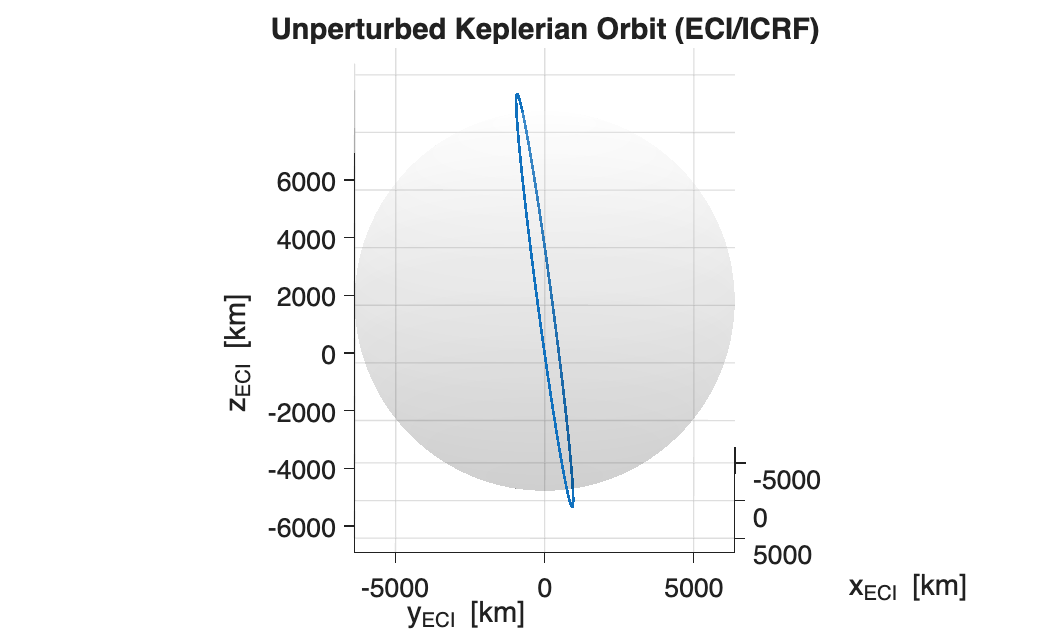

figure('Name','3D Orbit (ECI)');
plot3(r_eci(:,1), r_eci(:,2), r_eci(:,3), 'LineWidth', 1.0); hold on; grid on; axis equal;
% Draw a translucent Earth
[fX,fY,fZ] = sphere(80);
surf(Re*fX, Re*fY, Re*fZ, 'FaceAlpha', 0.1, 'EdgeColor', 'none'); colormap gray;
xlabel('x_{ECI} [km]'); ylabel('y_{ECI} [km]'); zlabel('z_{ECI} [km]');
title('Unperturbed Keplerian Orbit (ECI/ICRF)');
view(35,25);

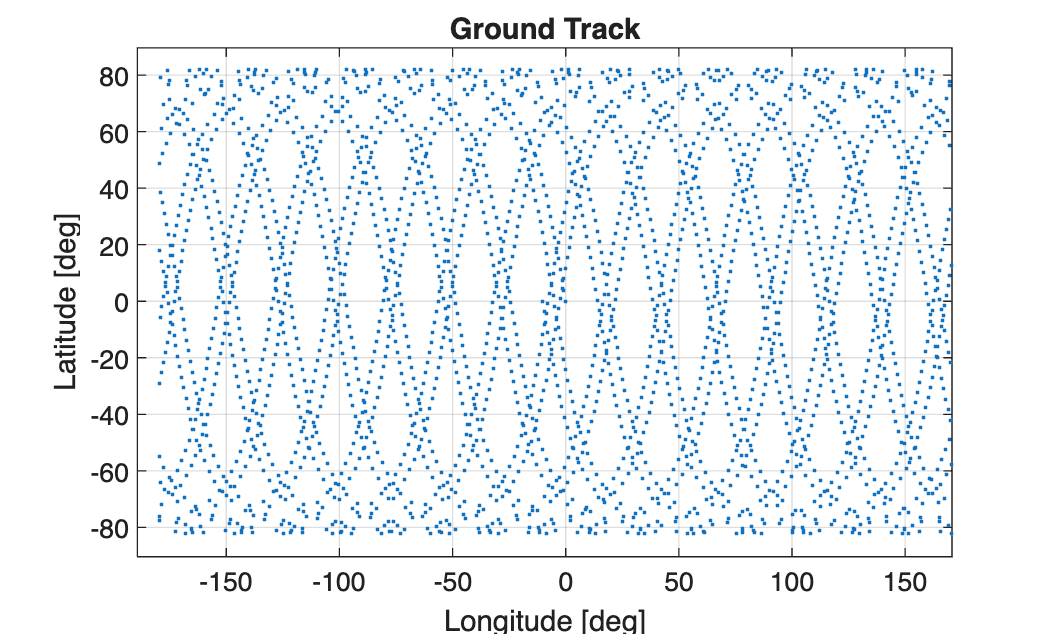


% -------- Ground Track --------
N  = size(r_eci,1);
lat_deg = zeros(N,1);
lon_deg = zeros(N,1);

for k = 1:N
    theta = theta_g0 + we*(t_vec(k) - t0);   % Earth rotation since t0
    % ECI -> ECEF: rotate about z by -theta
    R3m = [ cos(theta)  sin(theta) 0;
        -sin(theta)  cos(theta) 0;
        0           0     1];
    r_ecef = R3m * r_eci(k,:).';
    
    x = r_ecef(1); y = r_ecef(2); z = r_ecef(3);
    r_norm = hypot(hypot(x,y), z);
    
    lat = asin(z / r_norm);
    lon = atan2(y, x);
    
    lat_deg(k) = rad2deg(lat);
    lon_deg(k) = rad2deg(lon);
end

% Wrap longitudes to [-180,180]
lon_deg = mod(lon_deg + 180, 360) - 180;

figure('Name','Ground Track');
plot(lon_deg, lat_deg, '.', 'MarkerSize', 4); grid on;
xlim([-180 180]); ylim([-90 90]);
xlabel('Longitude [deg]'); ylabel('Latitude [deg]');
title('Ground Track');